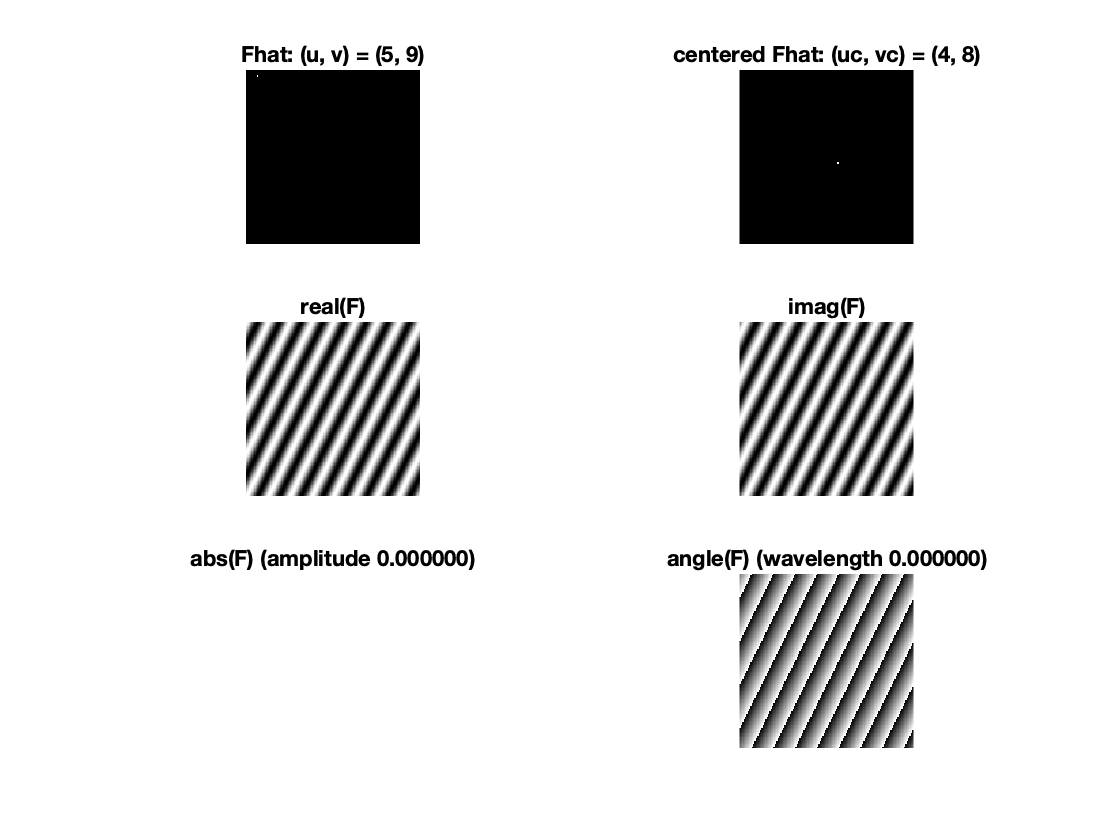


%1.3
Fhat = zeros(128, 128);

p=5;q=9;
Fhat(p , q ) = 1;

F=ifft2(Fhat);
Fabsmax = max(abs(F(:)));

p1=9;q1=5;
p2=17;q2=9;
p3=17;q3=121;
p4=5;q4=1;
p5=125;q5=1;


figure(1)
fftwavetemplate(p,q,128);

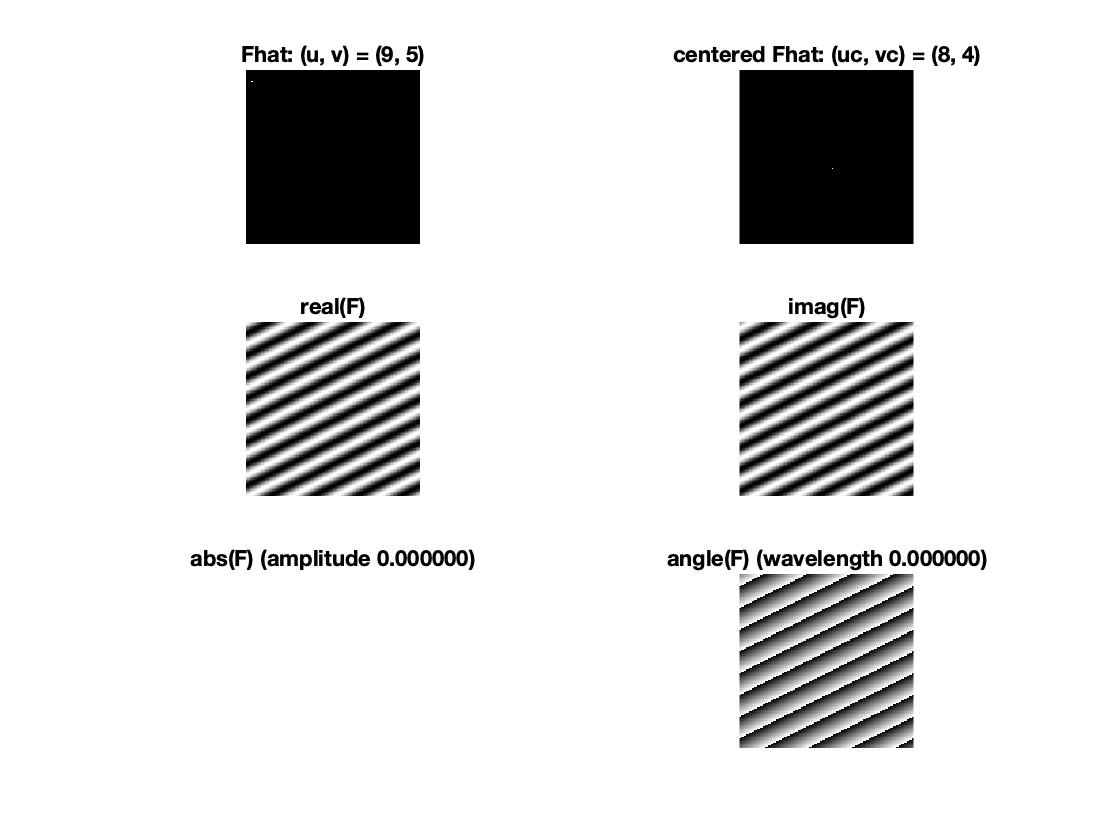

figure(2)
fftwavetemplate(p1,q1,128);

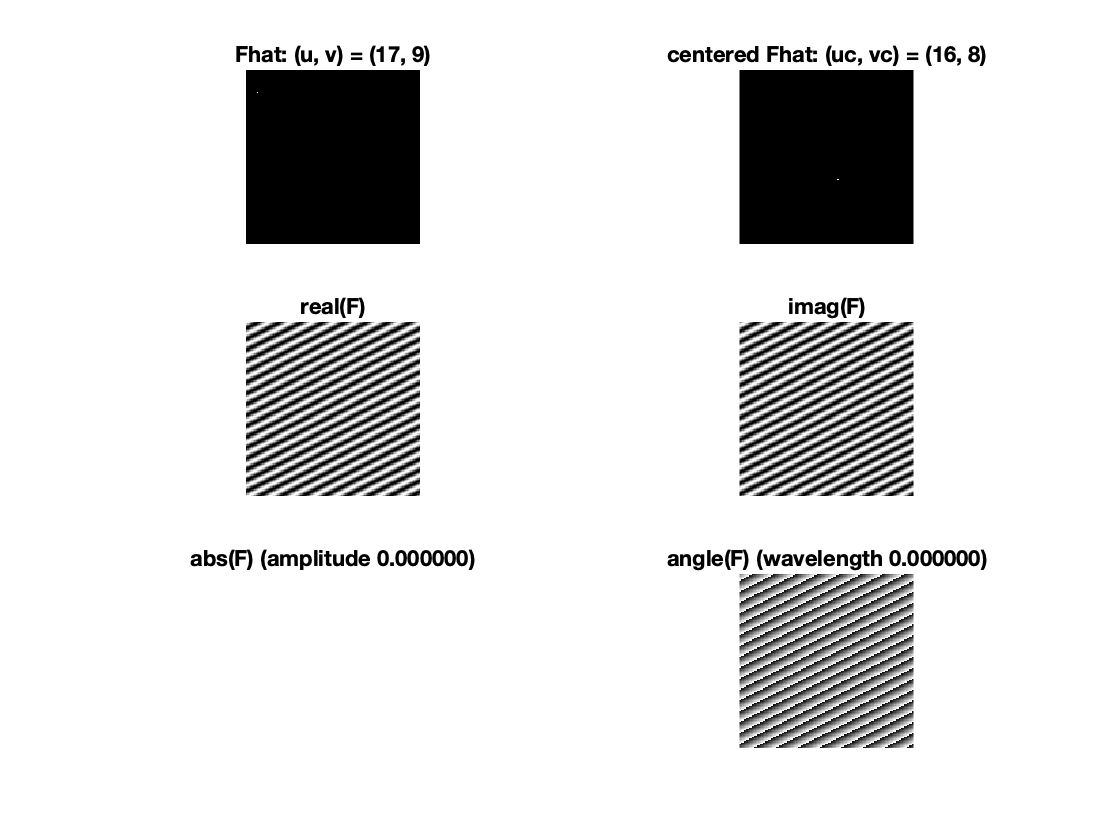

figure(3)
fftwavetemplate(p2,q2,128);

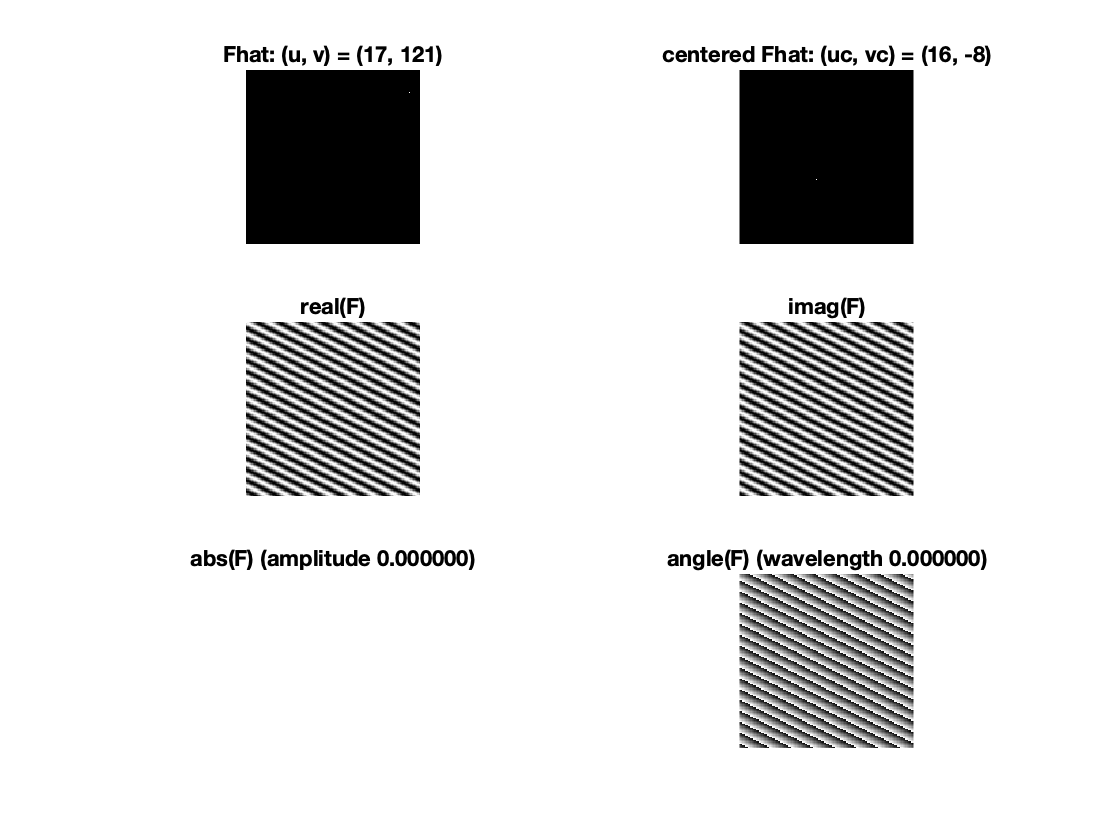

figure(4)
fftwavetemplate(p3,q3,128);

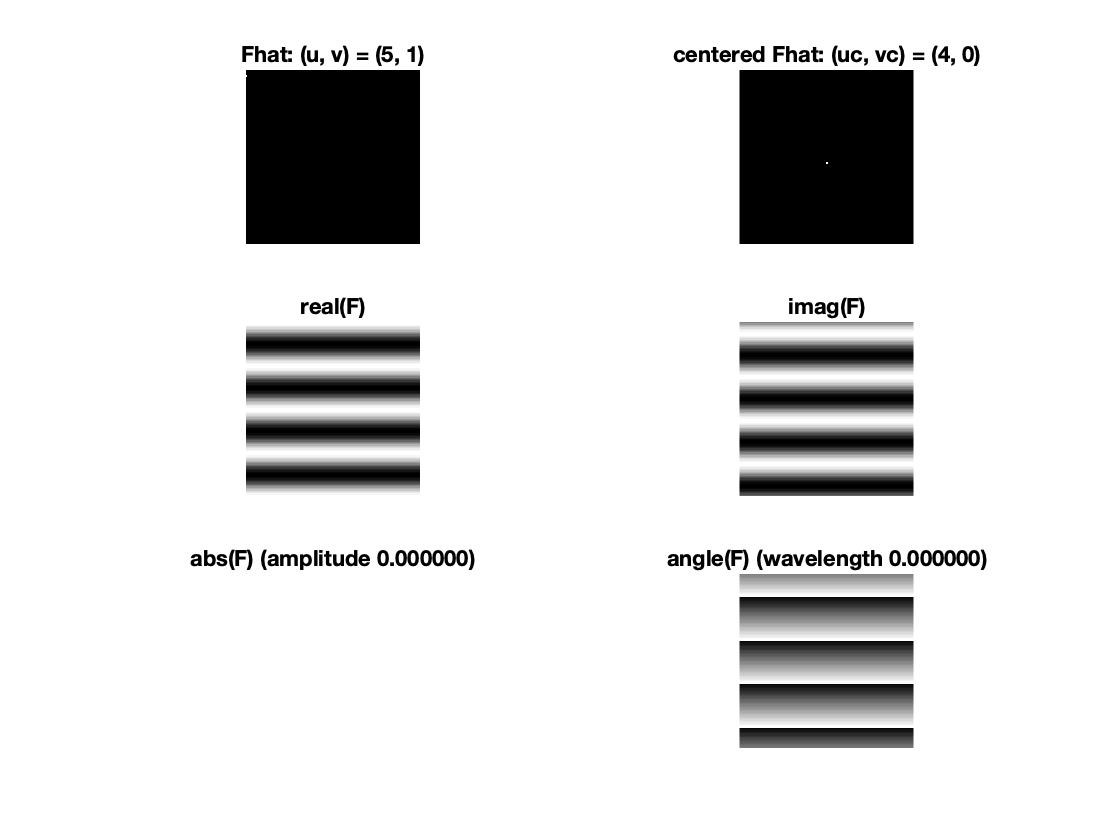

figure(5)
fftwavetemplate(p4,q4,128);

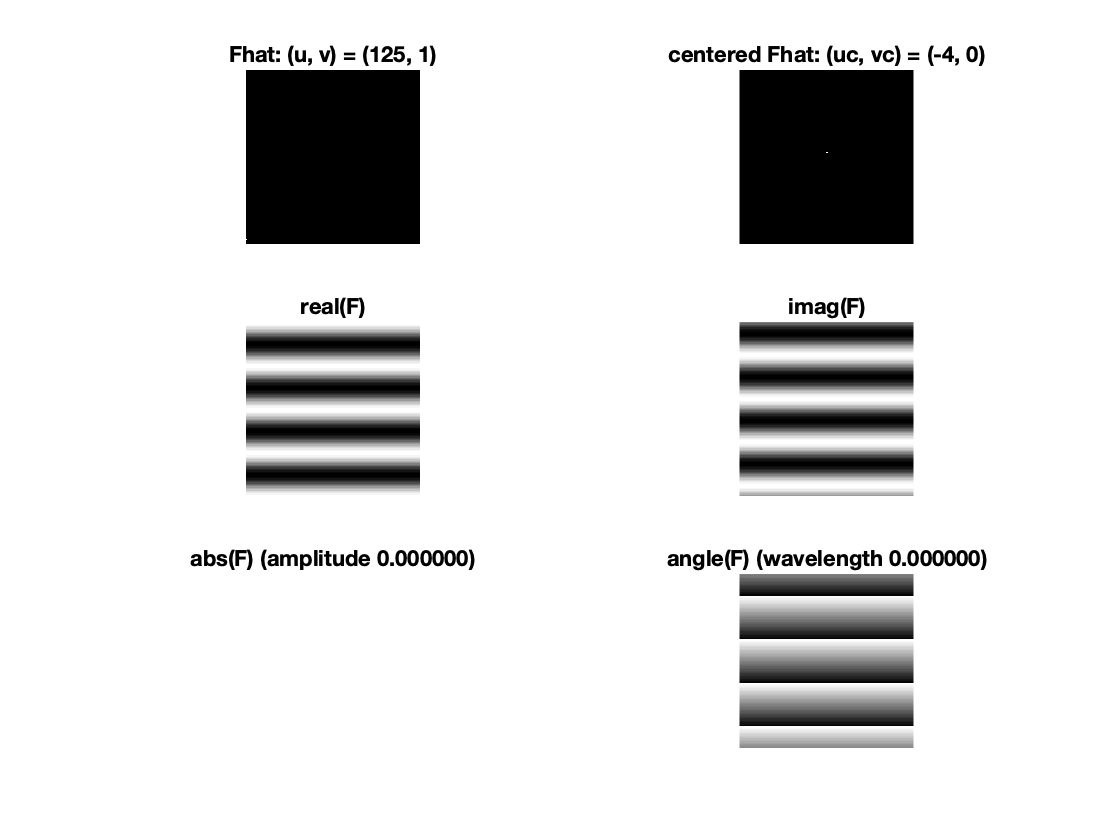

figure(6)
fftwavetemplate(p5,q5,128);

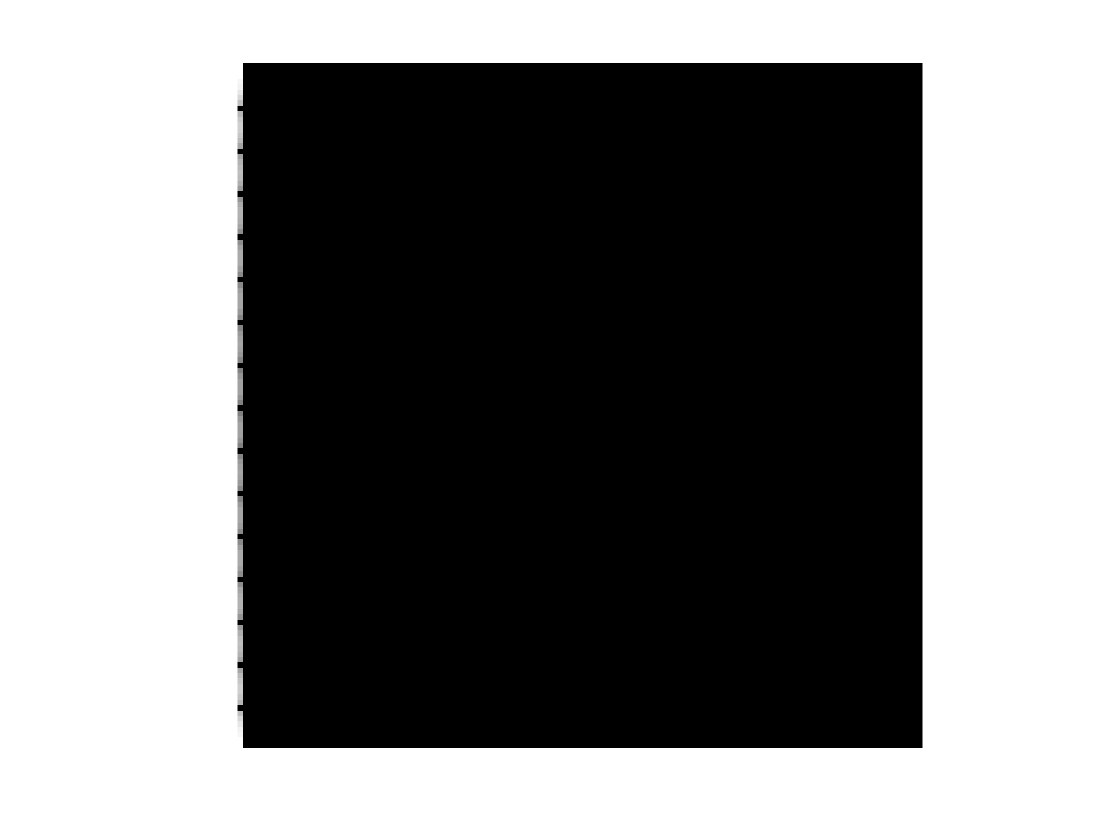


%---------------------------
%1.4 linearity
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

figure(7)
showgrey(log(1 + abs(Fhat)));

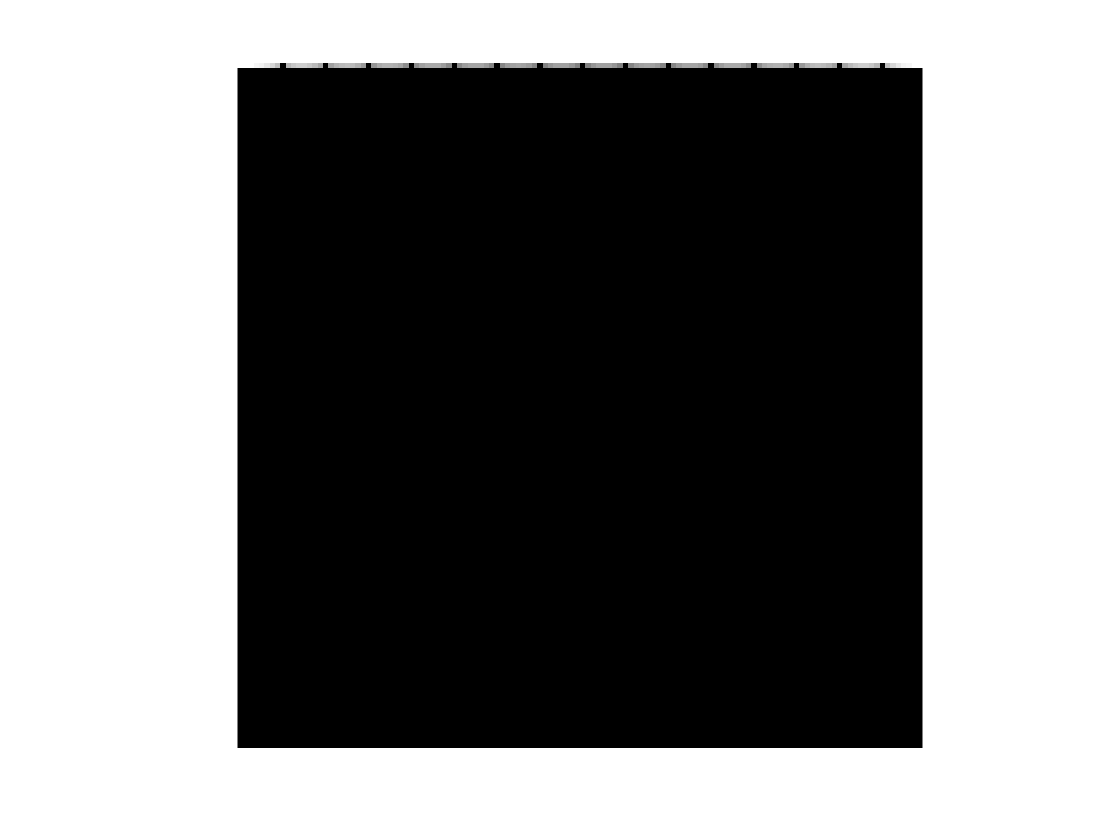

figure(8)
showgrey(log(1 + abs(Ghat)));

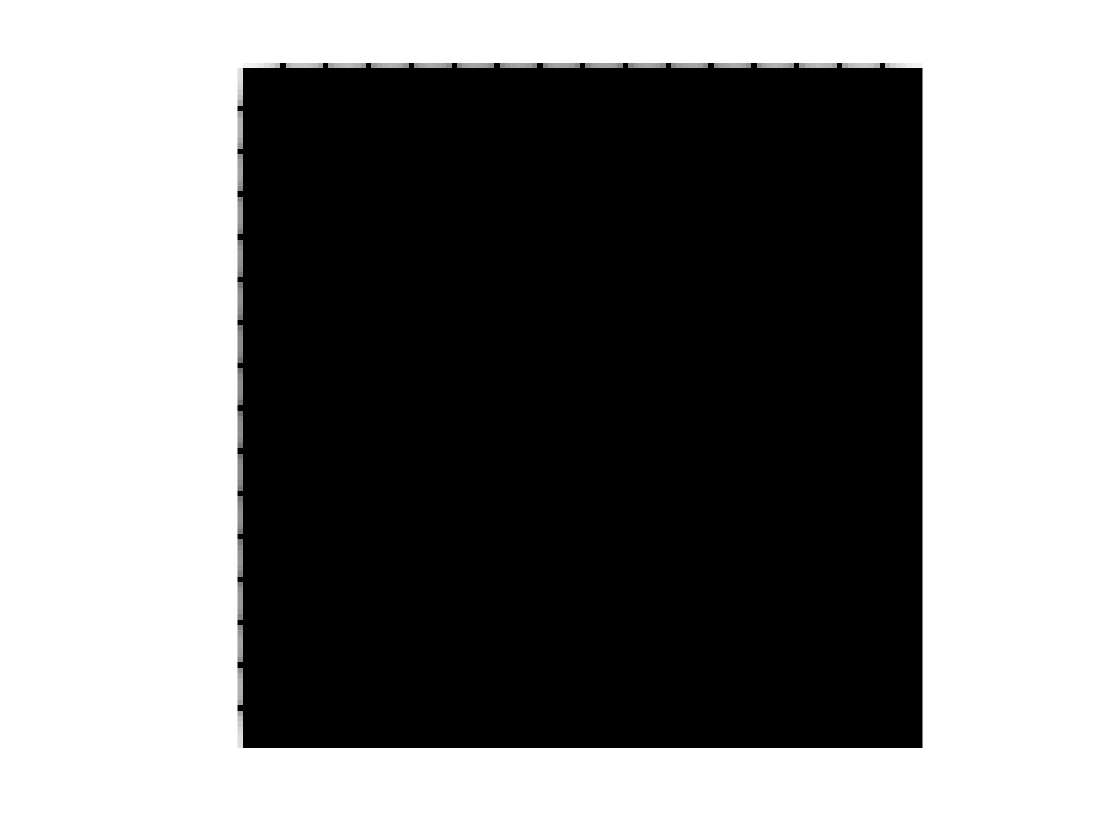

figure(9)
showgrey(log(1 + abs(Hhat)));

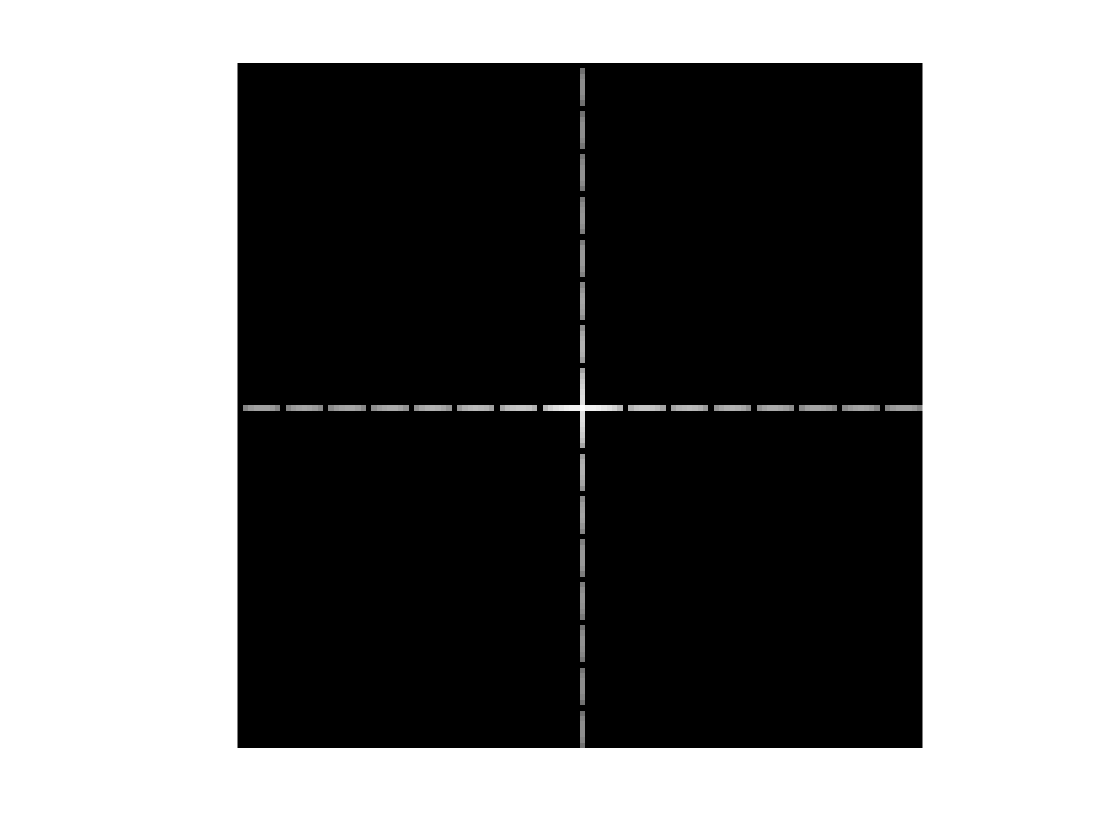

figure(10)
showgrey(log(1 + abs(fftshift(Hhat))));


showfs(Hhat)

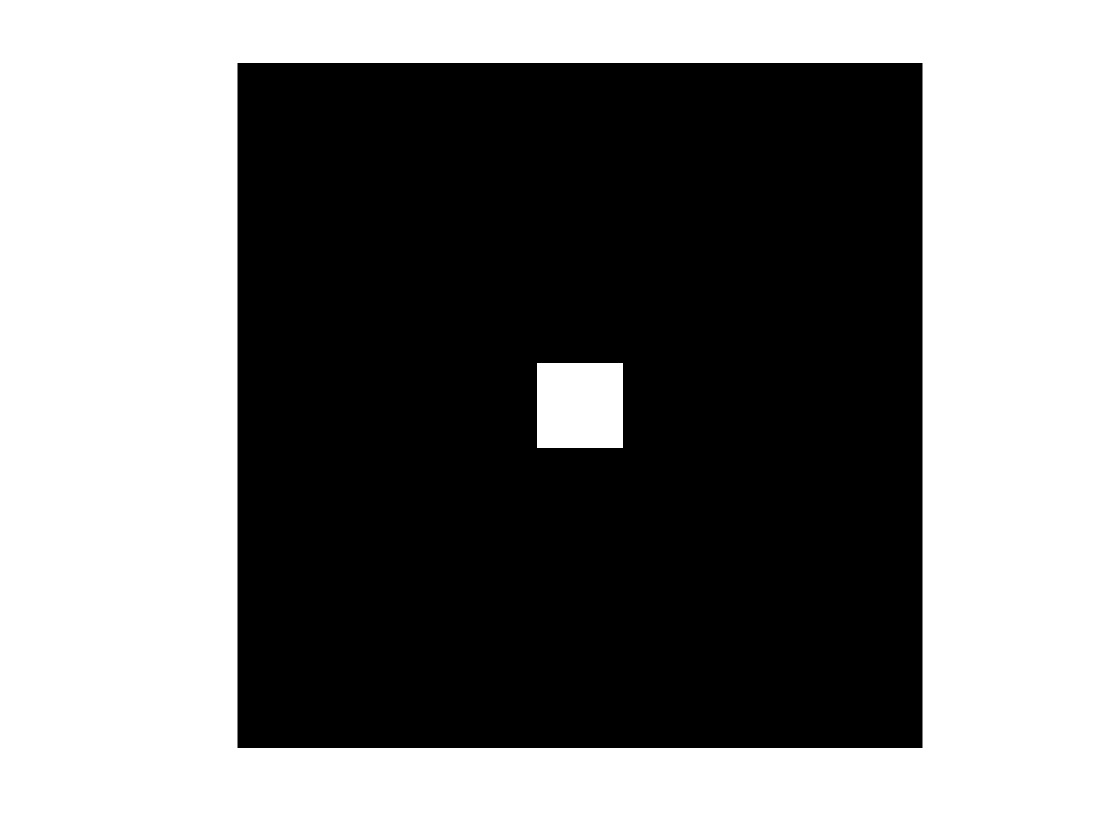


%--------------------------
%1.5 multiplication

showgrey(F .* G); %point-wise multiplication

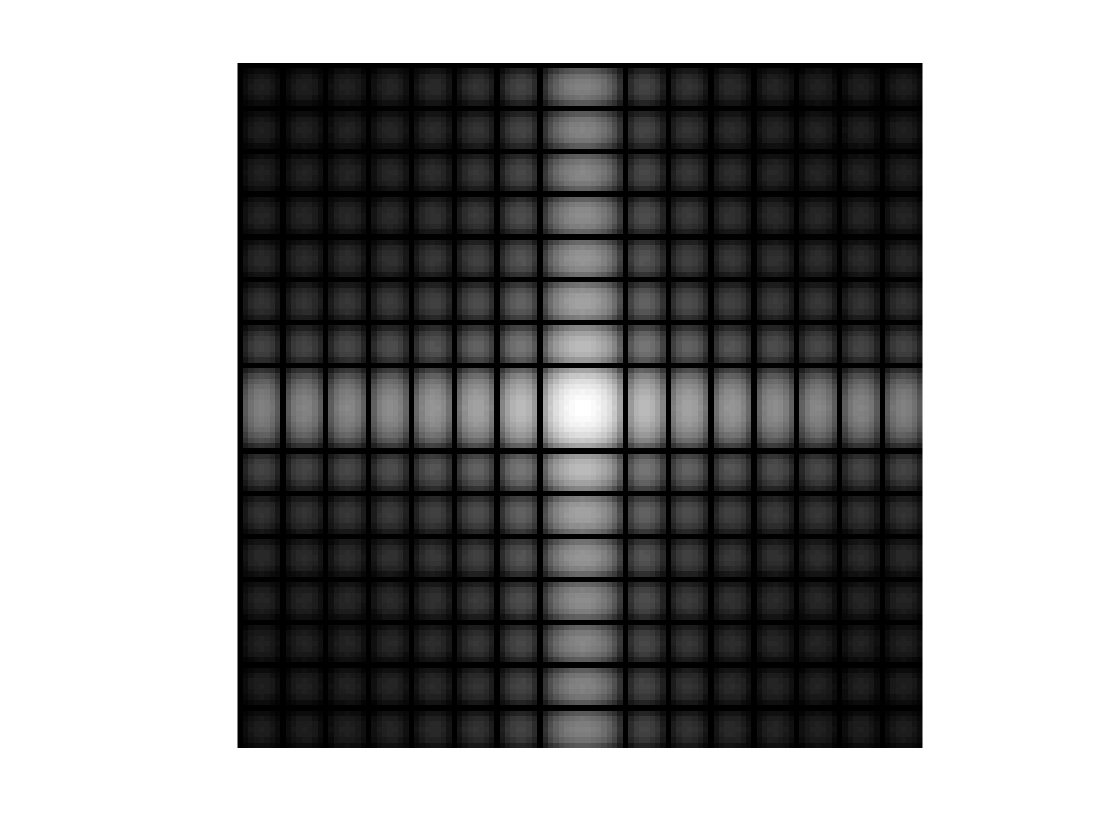

showfs(fft2(F .* G));

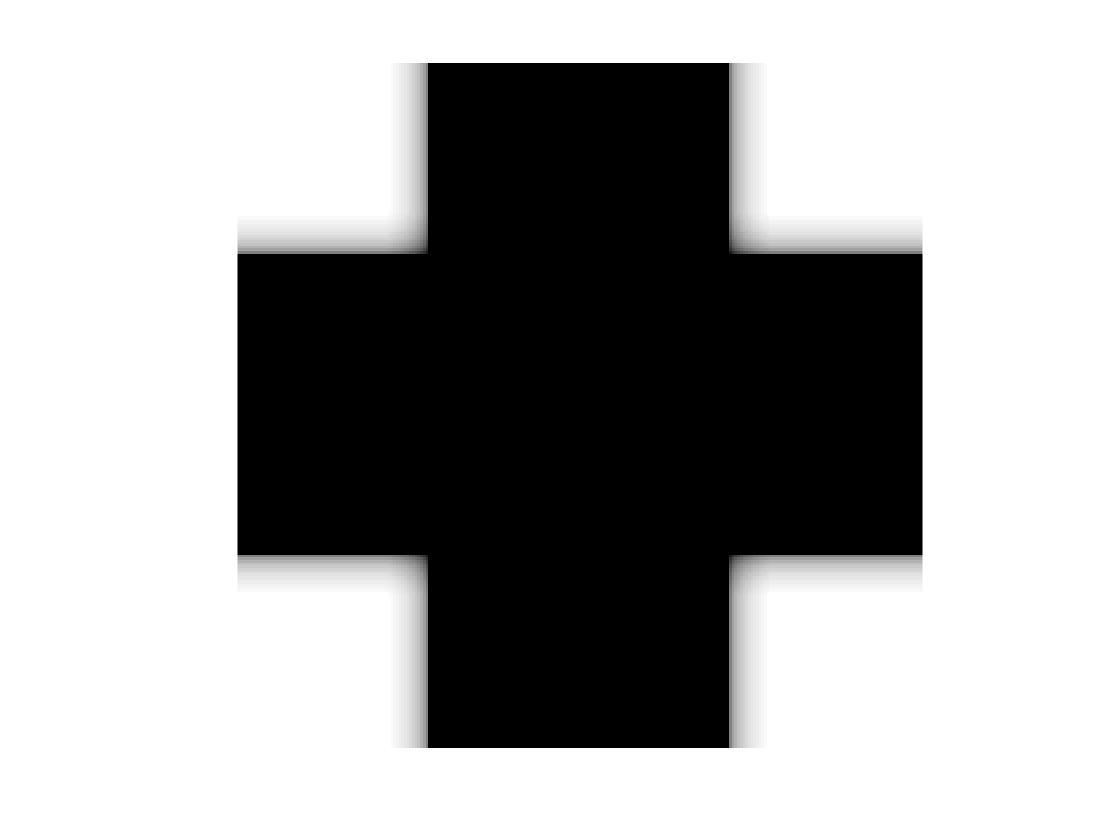



w=conv2(F,G); %convolution
showfs(w)

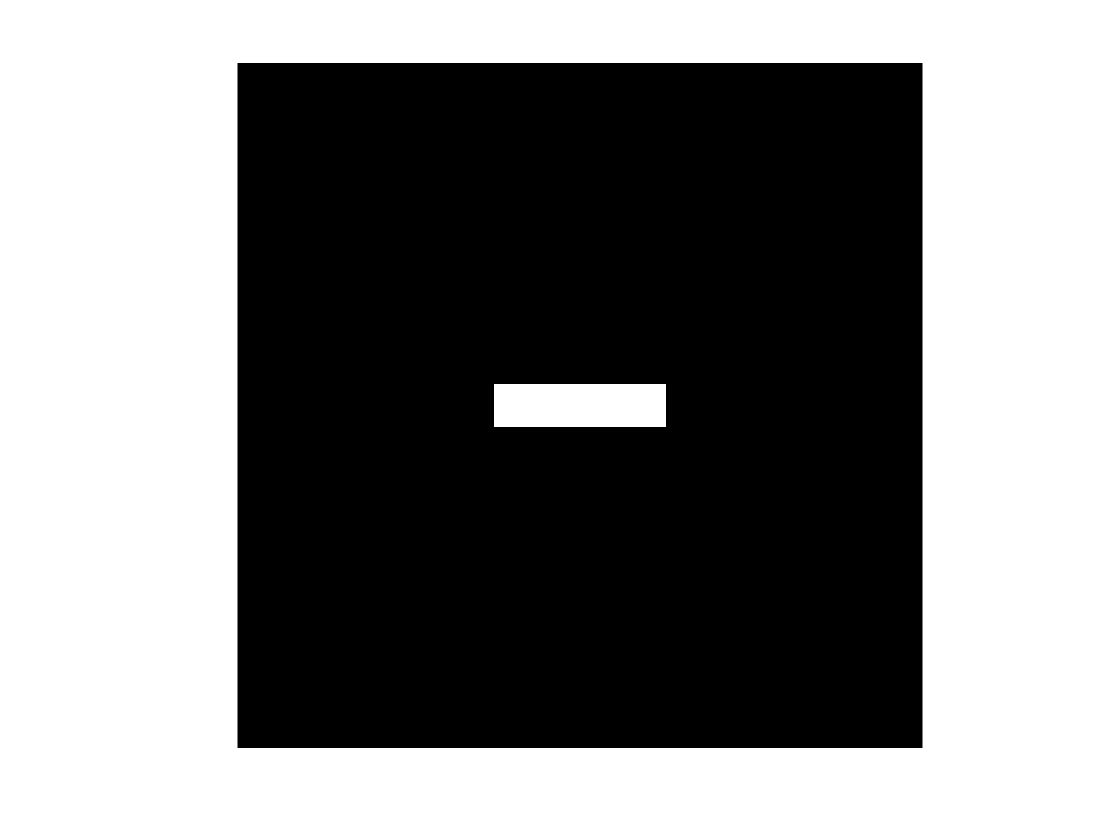

%------------------------
%1.6 scaling

Ftest = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];
showgrey(Ftest)

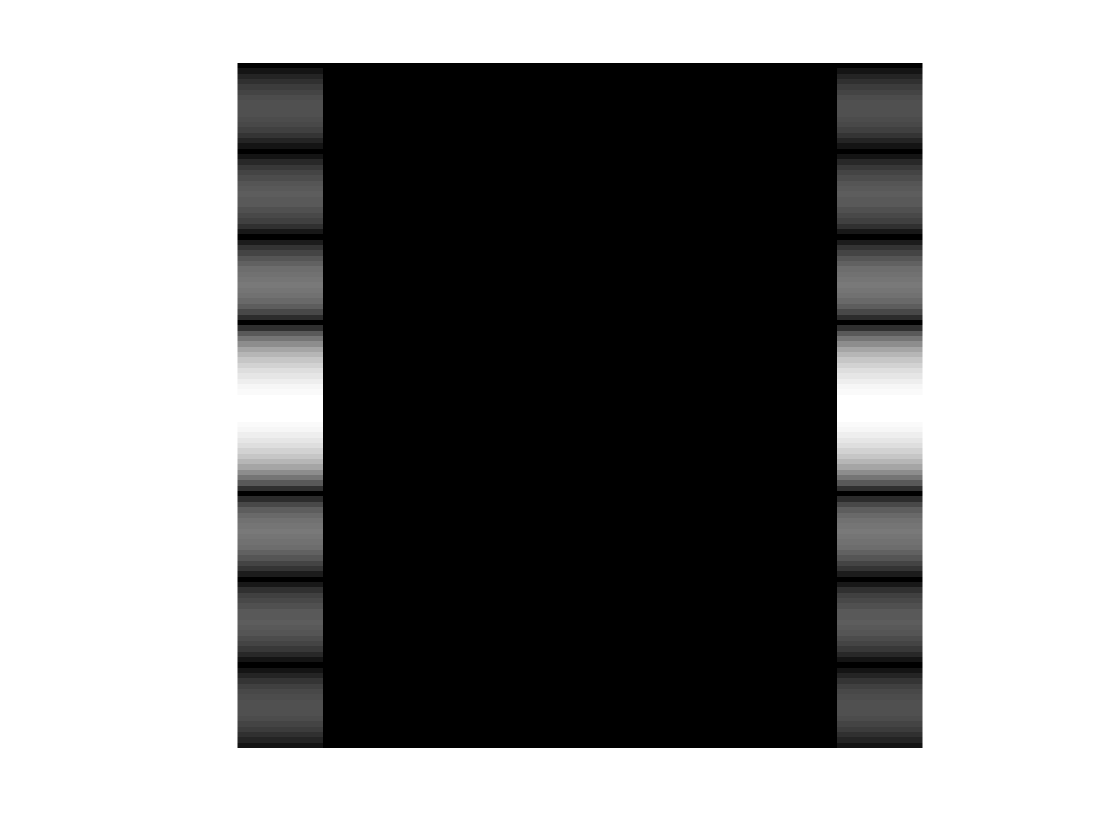

Ftrans=fft(Ftest);
showfs(Ftrans)

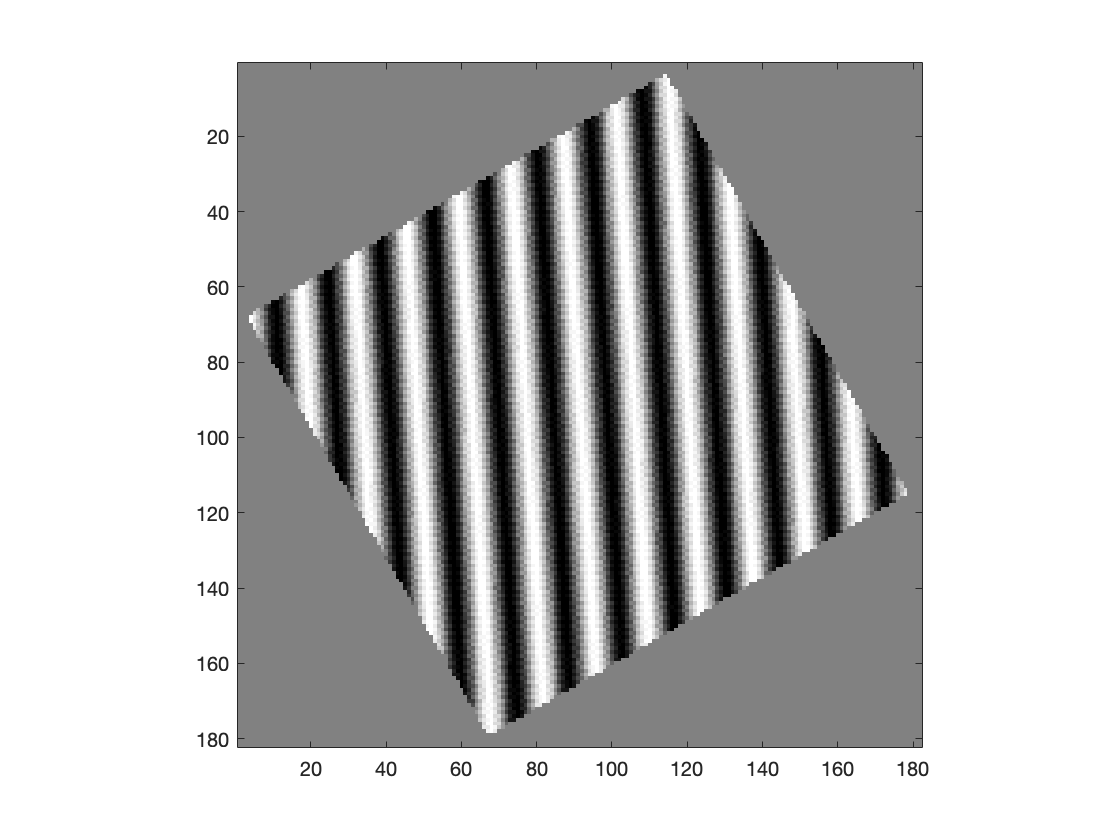


%------------------------
%1.7 rotation

Fhat = zeros(128, 128);
p=5;q=9;
Fhat(p , q ) = 1;
F=ifft2(Fhat);

alpha=30;
G = rot(F, alpha );
showgrey(real(G)) %real?
axis on

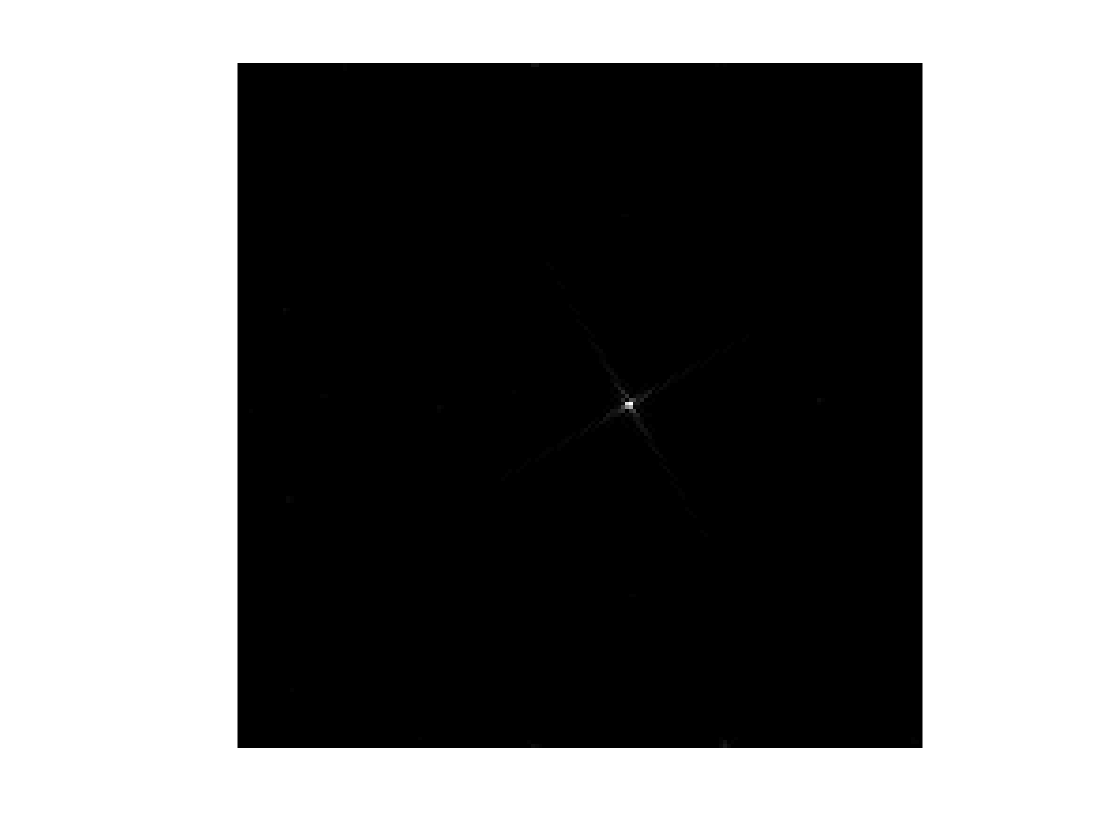

Ghat = fft2(G);
showfs(Ghat)

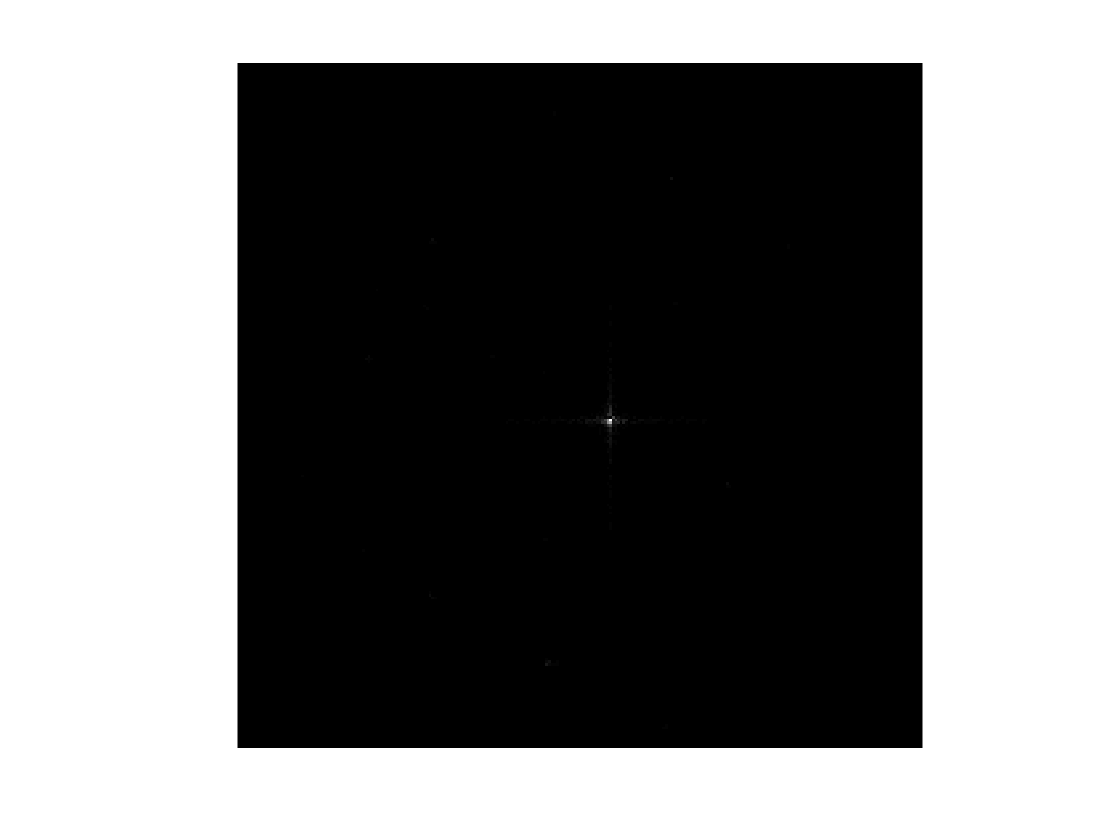

Hhat = rot(fftshift(Ghat), -alpha );
showgrey(log(1 + abs(Hhat)))

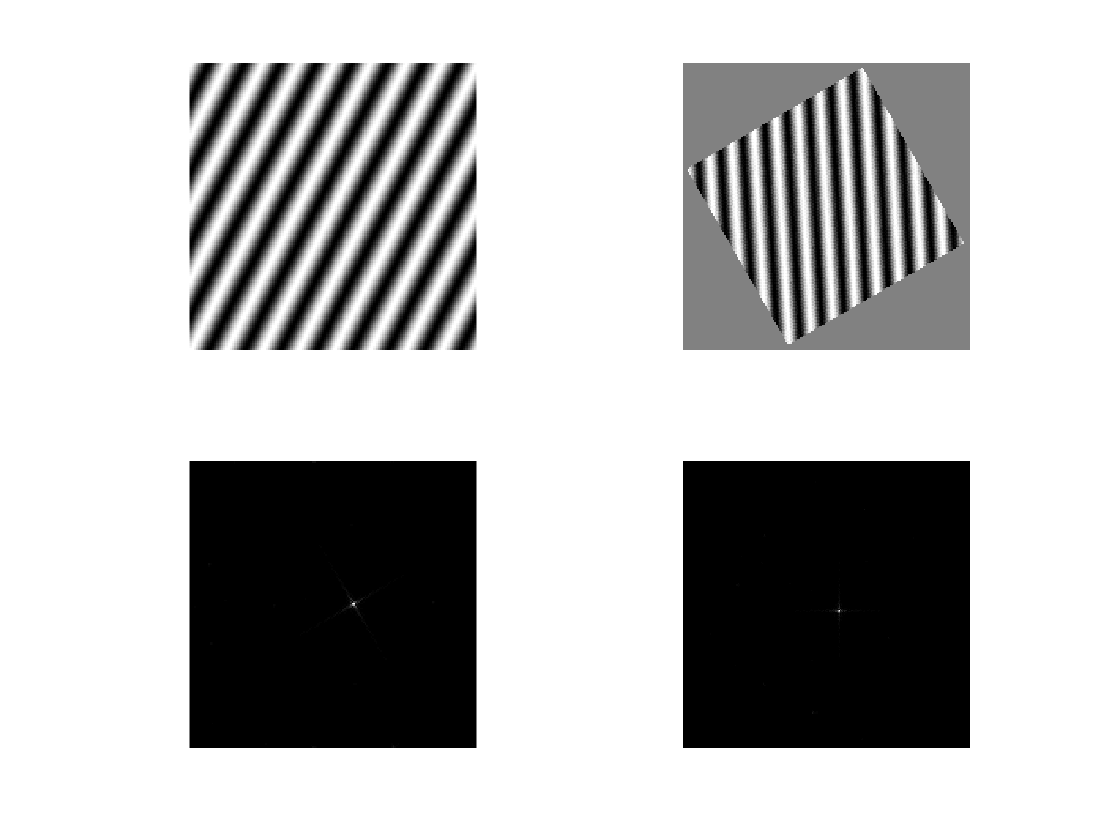

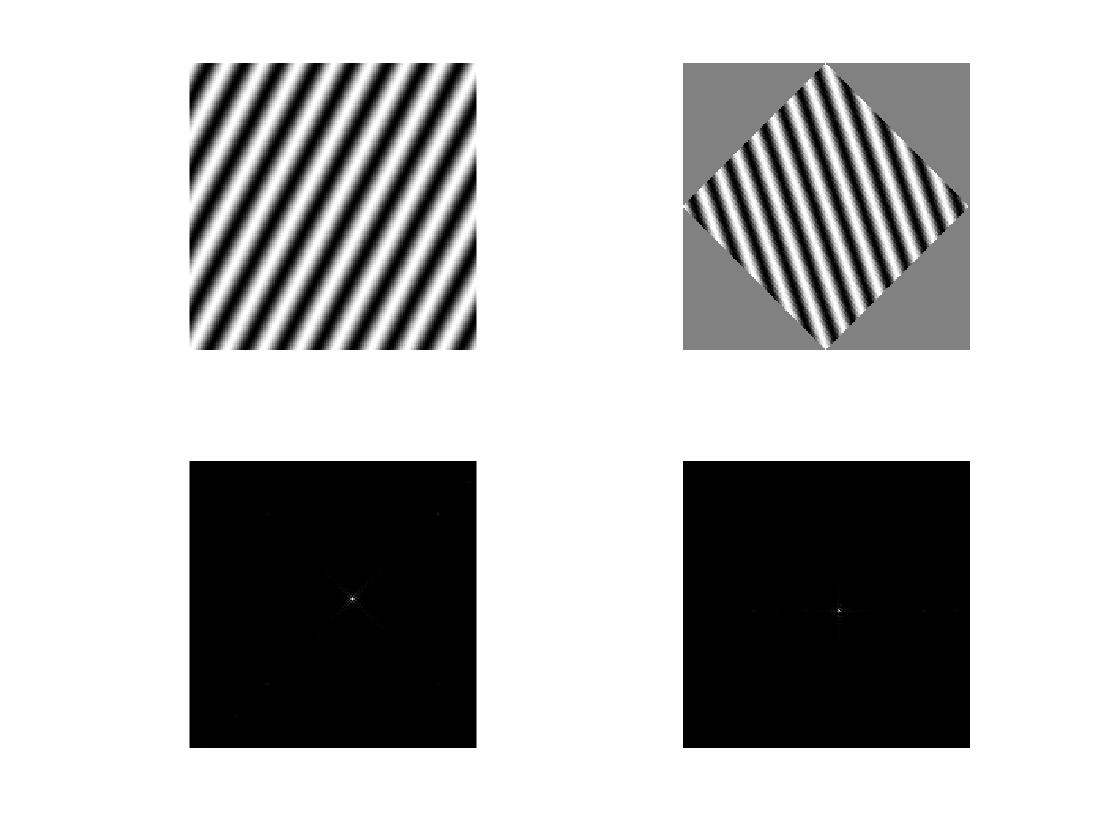

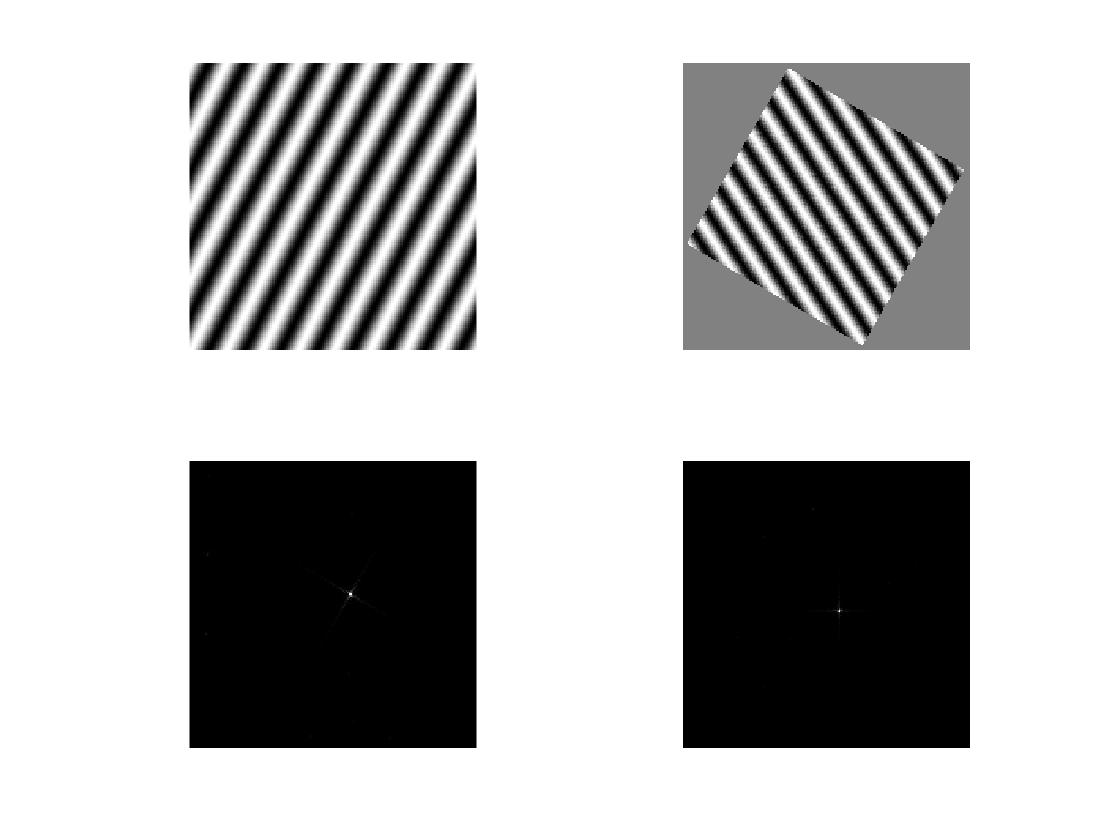

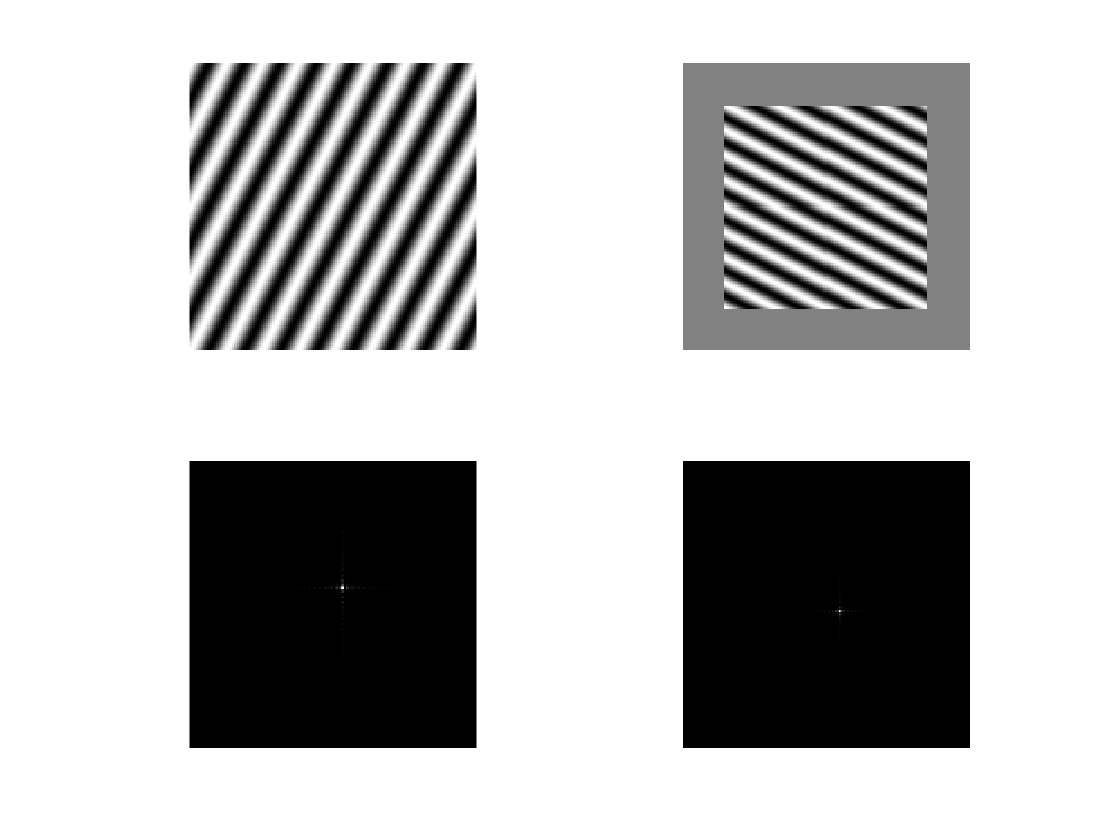


alpha=[30,45,60,90];
j=11;
for i=1:length(alpha)
    G = rot(F, alpha(i));
    Ghat = fft2(G);
    Hhat = rot(fftshift(Ghat), -alpha(i) );
    figure(i)

    subplot(2,2,1)
    showgrey(real(F))
    subplot(2,2,2)
    showgrey(real(G))
    subplot(2,2,3)
    showfs(Ghat)
    subplot(2,2,4)
    showfs(Hhat)
    showgrey(log(1 + abs(Hhat)))
    j=j+1;
end


%-------------------
%1.8

type pow2image;


function pixels = pow2image(inpic, a)

% POW2IMAGE(inpic, threshold) -- Power spectrum as negative power of two
%
% POW2IMAGE performs a transformation in the Fourier domain such 
% that the phase information is preserved, whereas the magnitude 
% is REPLACED BY a power spectrum of the form
%
% |Fourier|^2 \sim 1/(a + |omega|^2)

ftransform = fft2(inpic);

% Generate the power spectrum in centered frequency coordinates
% (note that the factor (pi/umax) corresponds to (2*pi/usize))
[usize vsize] = size(ftransform);
umax = usize/2;
vmax = vsize/2;
[u v] = meshgrid(umax - usize : umax - 1, vmax - vsize : vmax - 1);
pow2spectrum = 1 ./ (a + ((pi * u/umax).^2 + (pi * v/vmax).^2));

% Move the origin of the power spectrum to the lower left corner
pow2spectrum = fftshift(pow2spectrum);

% Replace the power spectrum (NOT a linear operation)
modtransform = pow2spectrum .* exp(i * angle(ftransform));

pixels = real(ifft2(modtransform));


a = 10e-10;
img1 = phonecalc128;
img2 = few128;
img3 = nallo128;
%figure(15)
pow = pow2image(img1, a);
rand = randphaseimage(img1);
%showfs(pow)

pow = pow2image(img2, a);
rand = randphaseimage(img2);

pow = pow2image(img3, a);
rand = randphaseimage(img3);
